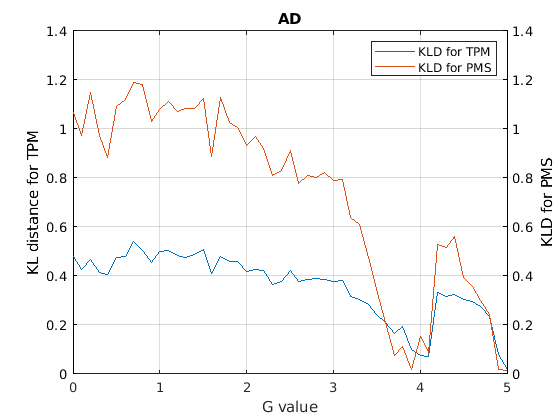

clear all
close all
% 加载数据
load results_ad.mat
load pms_ad_emp.mat
pms_ad_sim = zeros(51,3);
for i = 1:51
    pms_ad_sim(i,:) = results(i).pms_ad_sim;
end% 计算KL散度
kl_dist = calculateKLDivergences_test(pms_ad, pms_ad_sim);
kl_dist = kl_dist';
% 获取G_value
G_value = [results.G_value];
kl_dist_tpm = [results.kl_distance];
% 提取并转换KL散度为实数
kl_distances = real(kl_dist_tpm);

% 创建图形并绘制第一个数据集
figure;
yyaxis left; % 激活左侧y轴
plot(G_value, kl_distances, '-');
xlabel('G value');
ylabel('KL distance for TPM');
ylim([0,1.4]);
% 设置左侧y轴的颜色
ax = gca;
ax.YColor = 'k';

% 添加图的标题和网格
% title('G value vs KL distance');
grid on;

% 绘制第二个数据集到右侧y轴
yyaxis right; % 激活右侧y轴
plot(G_value, kl_dist, '-');
ylabel('KLD for PMS');
ylim([0,1.4]);

% 设置右侧y轴的颜色
ax.YColor = 'k';
title('AD')
legend('KLD for TPM','KLD for PMS');
% 确保两个数据集都显示在图中
hold off;